%% mlp_senza_svd.m
% Addestra un MLP (input→hidden→softmax) direttamente sui pixel dei volti.

clear; clc; close all;

%% Aggiungi path progetto
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/.../Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));

%% (Opzionale) Cartella results
results_path = fullfile(pwd,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) Iperparametri MLP
hidden_size   = 128;
epochs        = 100;
learning_rate = 0.005;
dropout_rate  = 0.3;

%% 2) Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


load('dataset/volti_dataset_Yale.mat','A','labels');  % A (m×n), labels
A = double(A)/255;                                    % normalizza pixel in [0,1]
[m, n] = size(A);                                     % m = n_pixel, n = n_samples

%% 3) Pre-processing (centratura + standardizzazione)
mean_face = mean(A,2);                                % [m×1]
std_face  = std(A,0,2) + 1e-6;                        % [m×1]
A_proc    = (A - mean_face) ./ std_face;              % [m×n]

%% 4) Prepara X e y
X           = A_proc';    % [n_samples × m]
y           = labels(:);  % [n_samples × 1]
num_classes = max(y);

%% 5) Split train/test (7 immagini per soggetto per train)
train_idx = []; test_idx = [];
for s = 1:num_classes
    idx = find(y==s);
    idx = idx(randperm(numel(idx)));
    train_idx = [train_idx; idx(1:7)];
    test_idx  = [test_idx; idx(8:end)];
end

X_train = X(train_idx, :);  % [n_train × m]
X_test  = X(test_idx,  :);  % [n_test  × m]
y_train = y(train_idx);     % [n_train × 1]
y_test  = y(test_idx);      % [n_test  × 1]

%% 6) One-hot encoding
n_train = size(X_train,1);
Y_train = zeros(num_classes, n_train);
for i = 1:n_train
    Y_train(y_train(i), i) = 1;
end

%% 7) Training MLP (funzione invariata)
fprintf('>>> Training MLP via gradient descent...\n');

>>> Training MLP via gradient descent...


[W1, b1, W2, b2, loss_hist] = mlp_gradient_descent( ...
    X_train, Y_train, hidden_size, epochs, learning_rate, dropout_rate);

[Epoch  10/100] Loss = 0.4725
[Epoch  20/100] Loss = 0.2569
[Epoch  30/100] Loss = 0.1226
[Epoch  40/100] Loss = 0.0929
[Epoch  50/100] Loss = 0.0479
[Epoch  60/100] Loss = 0.0761
[Epoch  70/100] Loss = 0.0561
[Epoch  80/100] Loss = 0.0601
[Epoch  90/100] Loss = 0.0383
[Epoch 100/100] Loss = 0.0384



%% 8) Valutazione sul test set
Z1     = W1 * X_test' + b1;     % [hidden_size × n_test]
A1     = max(0, Z1);            % ReLU
Z2     = W2 * A1 + b2;          % [num_classes × n_test]
Z2     = Z2 - max(Z2,[],1);     % stabilità numerica
expZ   = exp(Z2);
A2     = expZ ./ sum(expZ,1);   % softmax
[~, y_pred] = max(A2, [], 1);
y_pred = y_pred';                % [n_test × 1]

acc = mean(y_pred == y_test) * 100;
fprintf('Accuracy MLP (test set): %.2f%%\n', acc);

Accuracy MLP (test set): 71.67%


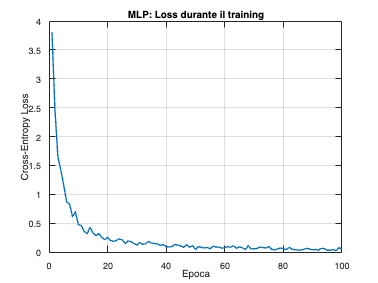


%% 9) Plot della loss
figure('Name','MLP: Cross-Entropy Loss','NumberTitle','off');
plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Cross-Entropy Loss');
title('MLP: Loss durante il training');
grid on;


% (Opzionale) Salva pesi e grafico
% save(fullfile(results_path,'mlp_weights.mat'),'W1','b1','W2','b2');
% saveas(gcf, fullfile(results_path,'loss_mlp.png'));

funzione mlp_gradient

function [W1,b1,W2,b2,loss_history] = ...
    mlp_gradient_descent(X, Y_onehot, hidden_size, epochs, lr, dropout_rate)

% MLP_GRADIENT_DESCENT Addestra una MLP a un hidden layer con discesa
% del gradiente esplicita.
% 
% Input:
%   X            dimensioni [n_samples x input_size]
%   Y_onehot     dimensioni [n_classes x n_samples]
%   hidden_size  numero di neuroni nel layer nascosto
%   epochs       numero di epoche
%   lr           learning rate
%   dropout_rate tasso di dropout in training
%
% Output:
%   W1, b1       pesi e bias del primo layer
%   W2, b2       pesi e bias del secondo layer
%   loss_history vettore [1 x epochs] con il valore di loss ad ogni epoca

    [n_samples, input_size] = size(X);
    n_classes = size(Y_onehot,1);

    % He initialization
    rng(0);
    W1 = randn(hidden_size, input_size) * sqrt(2/input_size);
    b1 = zeros(hidden_size,1);
    W2 = randn(n_classes, hidden_size)* sqrt(2/hidden_size);
    b2 = zeros(n_classes,1);

    X_T = X';       % [input_size x n_samples]
    loss_history = zeros(1,epochs);

    for epoch = 1:epochs
        % ---- Forward pass ----
        Z1 = W1*X_T + b1;               
        A1 = max(0, Z1);                % ReLU

        % ---- Dropout (inverted) ----
        M = (rand(size(A1)) > dropout_rate) / (1-dropout_rate);
        A1_drop = A1 .* M;             

        Z2 = W2*A1_drop + b2;           
        % Softmax (stable)
        Z2 = Z2 - max(Z2,[],1);
        expZ = exp(Z2);
        A2 = expZ ./ sum(expZ,1);      % [n_classes x n_samples]

        % ---- Compute cross-entropy loss ----
        eps = 1e-12;
        L = -sum(log(sum(A2 .* Y_onehot,1) + eps))/n_samples;
        loss_history(epoch) = L;
        if mod(epoch,10)==0
            fprintf('[Epoch %3d/%3d] Loss = %.4f\n', epoch, epochs, L);
        end

        % ---- Backward pass ----
        dZ2 = A2 - Y_onehot;                         % [C x N]
        dW2 = (dZ2 * A1_drop') / n_samples;          % [C x H]
        db2 = sum(dZ2,2) / n_samples;                % [C x 1]

        dA1 = W2' * dZ2;                             % [H x N]
        dZ1 = dA1 .* (Z1>0);                         % ReLU'
        dW1 = (dZ1 * X_T') / n_samples;              % [H x I]
        db1 = sum(dZ1,2) / n_samples;                % [H x 1]

        % ---- Gradient update ----
        W2 = W2 - lr * dW2;
        b2 = b2 - lr * db2;
        W1 = W1 - lr * dW1;
        b1 = b1 - lr * db1;
    end
end
